clc
clear all
load Observation_wb.mat
win = hann(512);
nfft = 512;
inc = 256;
shortfft = zeros(nfft/2+1,fix(size(X,1)/inc)+1,size(X,2));
a = 0;
for i = 0:inc:(size(X,1)-nfft);
    a = a+1;
    for j = 1:size(X,2);
        w = win.*X(i+1:i+nfft,j);
        t = fft(w,nfft);
        shortfft(:,a,j) = t(1:nfft/2+1);
    end
end
sfft = zeros(nfft/2+1,size(X,2));
for i = 1:a;
    for j = 1:(nfft/2+1);
        for k = 1 :size(X,2);
            sfft(j,k) = sfft(j,k)+shortfft(j,i,k)/a;
        end
    end
end
p_value = zeros(nfft/2+1,181)

p_value =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i = 1:(nfft/2+1)
    [c,b] = Pmusic_g(0.025,sfft,(i-1)/512*16000);
    for j = 1:181
      p_value(i,j) = c(j);
    end
end

V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V =   -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 =     0.0000
    0.0001
    0.0004
    0.0041


ind =      1
     2
     3
     4


vector1 =   -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 =   -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un =   -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


V = 4×4
  -0.2903 + 0.1899i  -0.0840 - 0.4537i   0.5264 + 0.3677i   0.4489 + 0.2299i
   0.1571 - 0.5802i   0.0238 + 0.5494i   0.2408 + 0.0509i   0.4991 + 0.1631i
   0.4699 + 0.4048i   0.5152 - 0.0835i  -0.2686 - 0.1057i   0.5024 + 0.0855i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i  -0.6662 + 0.0000i   0.4585 + 0.0000i


D = 4×4
    0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0004         0
         0         0         0    0.0041


d1 = 4×1
    0.0000
    0.0001
    0.0004
    0.0041


ind = 4×1
     1
     2
     3
     4


vector1 = 4×1
  -0.2903 + 0.1899i
   0.1571 - 0.5802i
   0.4699 + 0.4048i
  -0.3658 + 0.0000i


vector2 = 4×1
  -0.0840 - 0.4537i
   0.0238 + 0.5494i
   0.5152 - 0.0835i
  -0.4607 + 0.0000i


Un = 4×2
  -0.2903 + 0.1899i  -0.0840 - 0.4537i
   0.1571 - 0.5802i   0.0238 + 0.5494i
   0.4699 + 0.4048i   0.5152 - 0.0835i
  -0.3658 + 0.0000i  -0.4607 + 0.0000i


ans = zeros(181,1)

ans = 181×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


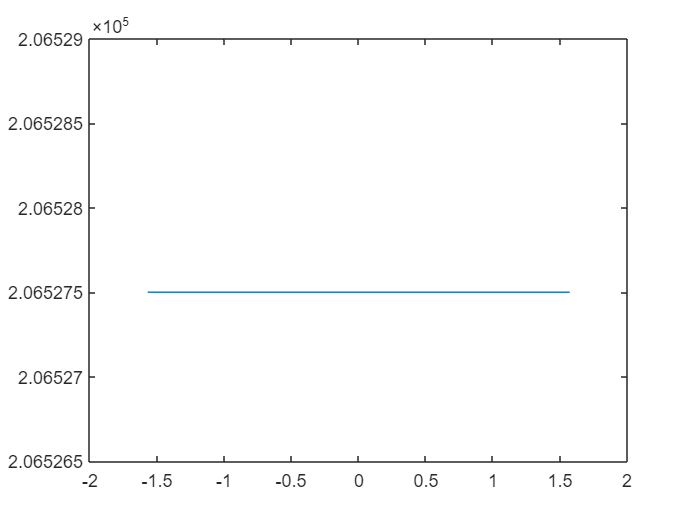

for i = 1:257
    ans(:,1) = ans(:,1) + p_value(1,:)';
end
plot(b,real(ans))